# Spike detection

Simulating the signal

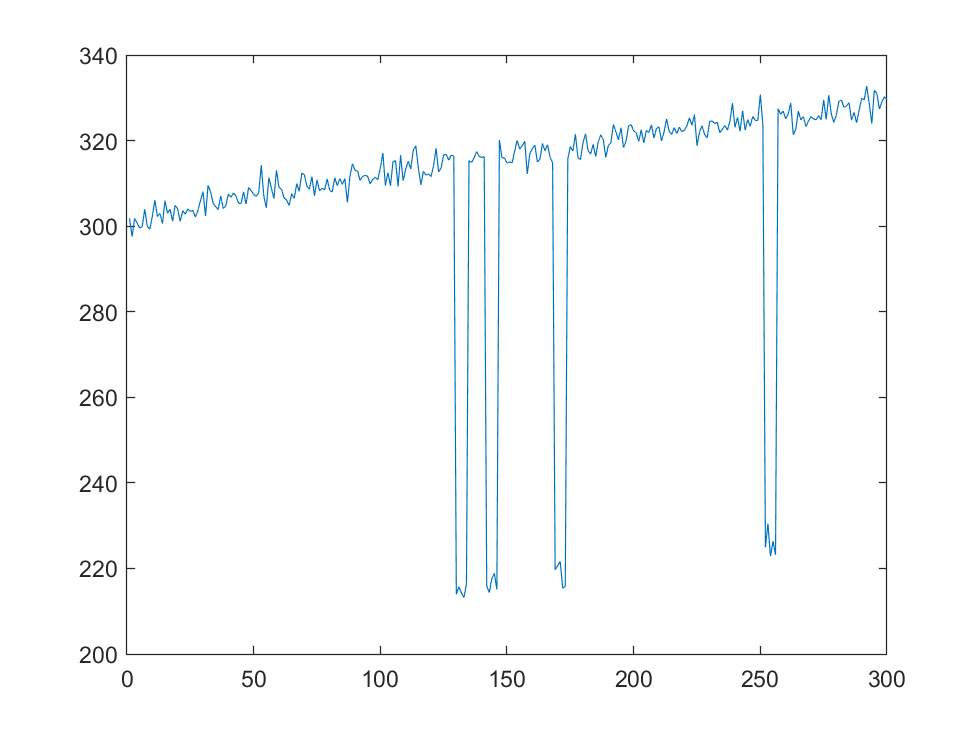

N = 300;
% s = 10*rand(N,1) + 100;
% spikeIndices = randi(N, [20, 1]);
% s(spikeIndices) = s(spikeIndices) - 50;
tAll = (1:N).';
s = 300 + 0.3*tAll.^(0.8) + 2*randn(N,1);
spikeIndices = randi(N, [4, 1]);
spikeIndices = [spikeIndices; spikeIndices+1; spikeIndices+2;...
    spikeIndices+3; spikeIndices+4];
s(spikeIndices) = s(spikeIndices) - 100;
plot(s)

Signal derivative

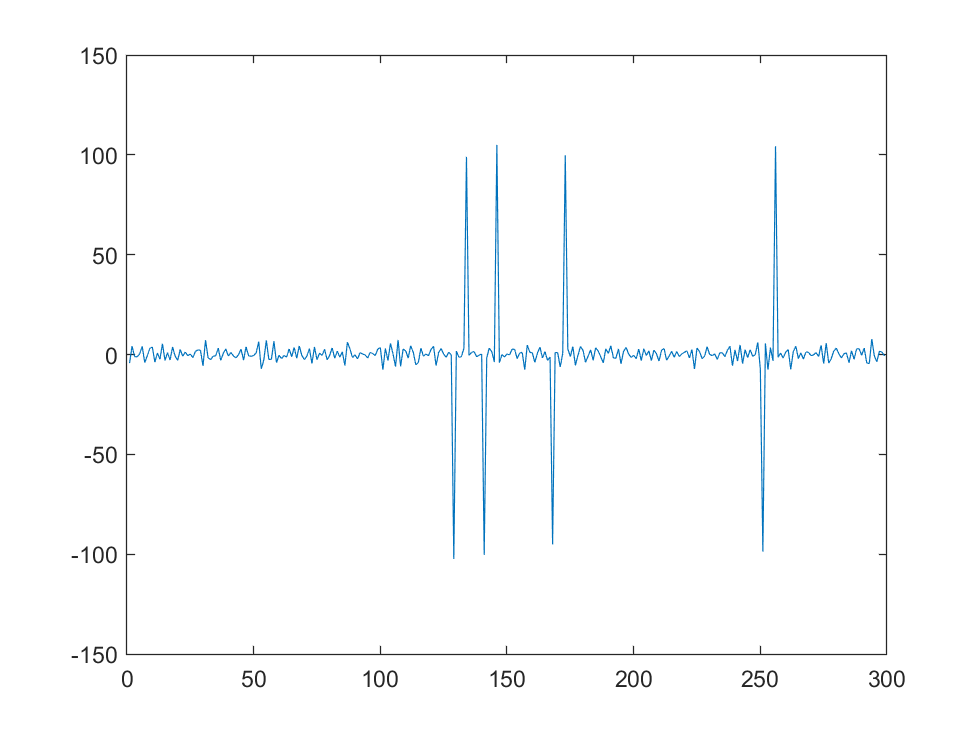

ds = diff(s);
plot(ds)

Deviation of the signal from its running average

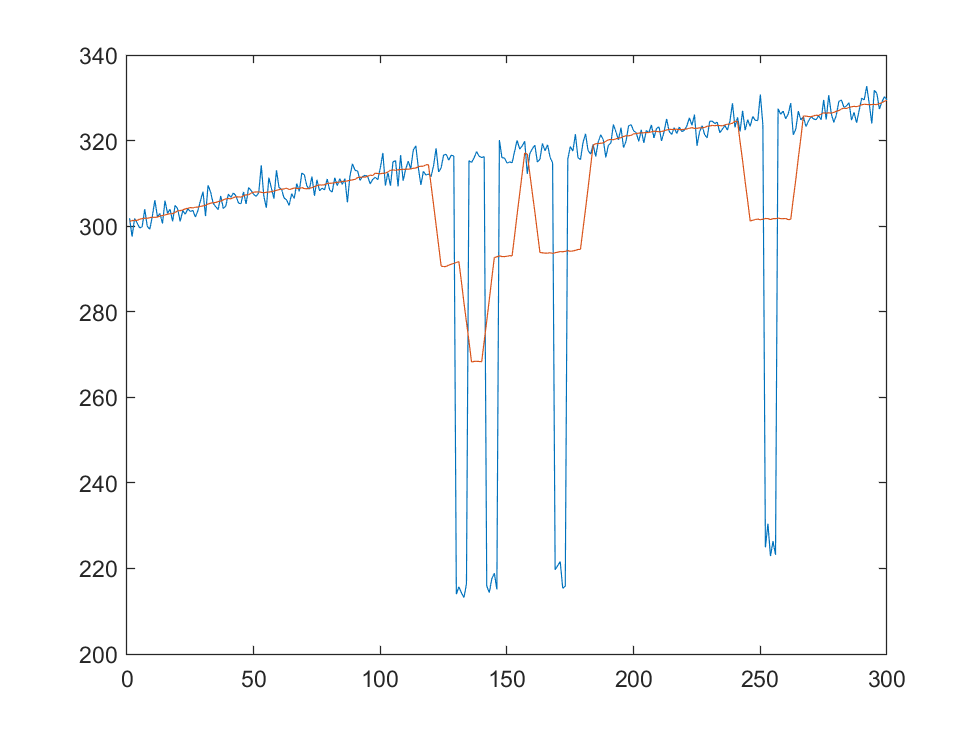

windowLength = 21;
sSmooth = movmean(s,windowLength);
figure;
plot((1:N).', s, (1:N).',sSmooth)

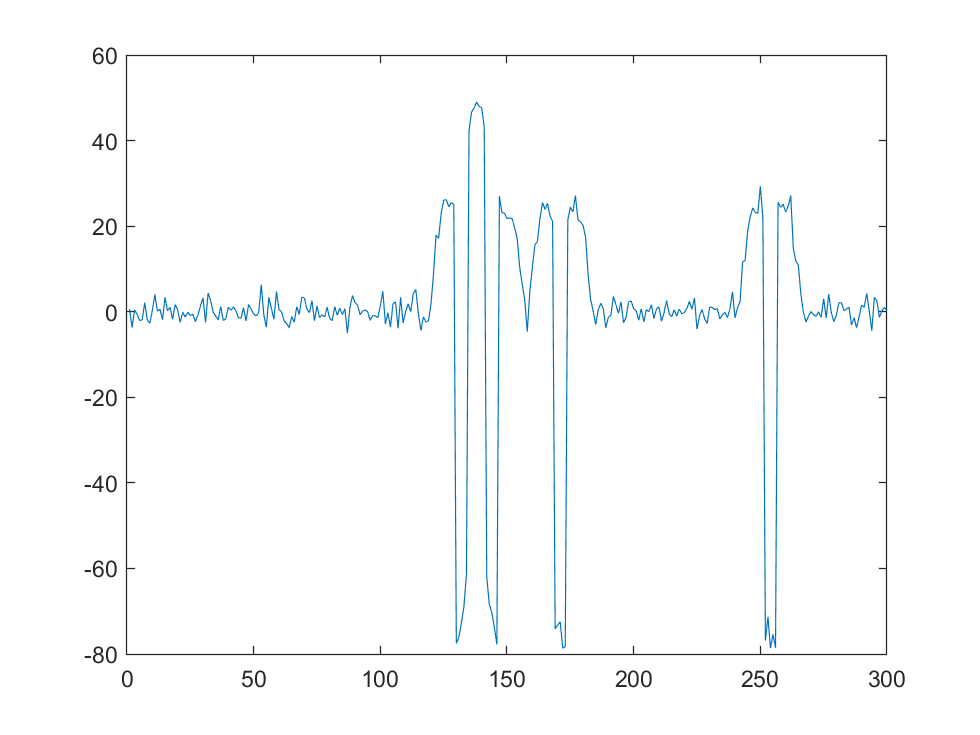

figure;
plot(s-sSmooth);